# Ground Truths Dataset 1

## Clear workspace and all figures

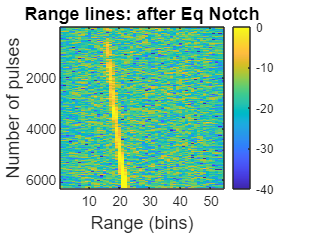


clear all;clc;close all

%% Load Data
[FileName,Path2RadarData,filter_index]=uigetfile('','Select Radar Dataset');
RadarData = load([Path2RadarData filesep FileName]);

%% Extract Range Profiles before, after Equalisation and after Notch filtering

RangeProfiles_BeforeEq = RadarData.RangeLines_BeforeEq;
RangeProfiles_AfterEq = RadarData.RangeLines_AfterEq;
RangeProfiles_AfterEqNotch = RadarData.RangeLines_AfterEQ_Notch;

%% Extract other radar parameters

 PRF_Hz = RadarData.Info.PRF_Hz;
 Bandwidth_Hz = RadarData.Info.Bandwidth_Hz;
 RangeStart_m = RadarData.Info.RangeStart_m;
 BlindRange_m = RadarData.Info.BlindRange_m;
 
[NumOfPulses,NumOfRangeBins]=size(RangeProfiles_AfterEqNotch);

%% Plot Range Profiles

fontsize1 = 12;
clims = [-40 0];

% Normalise data to have a peak of 0dB or 1 in linear scale
[MaxRangeLine MaxIdx] = max(max(abs(RangeProfiles_AfterEqNotch)));
MaxRangeLine = (1/2)*MaxRangeLine;

% Plot range lines
figure; axes('fontsize',fontsize1);
imagesc(20*log10(abs(RangeProfiles_AfterEqNotch)./MaxRangeLine),clims);
colorbar;
xlabel('Range (bins)','fontsize',fontsize1);
ylabel('Number of pulses','fontsize',fontsize1);
title('Range lines: after Eq Notch','fontsize',fontsize1);

## Detection Point Calculations for Dataset 1


%final variable of detection points
Target_locations_DS1 = zeros(NumOfPulses, NumOfRangeBins);

% Parameters for sections of data to screenshot
stepSize = 100;
numIterations = ceil(NumOfPulses/stepSize)

numIterations = 64

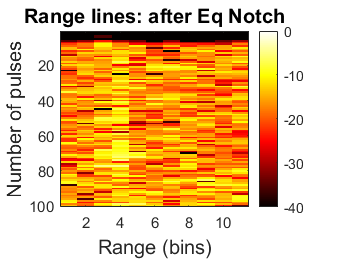

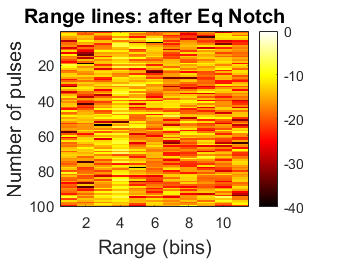

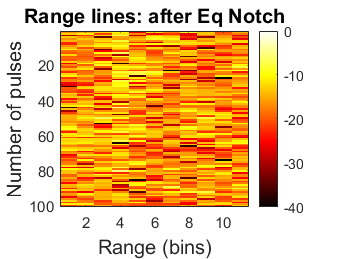

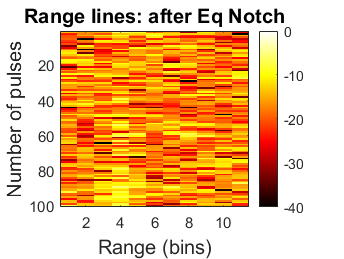

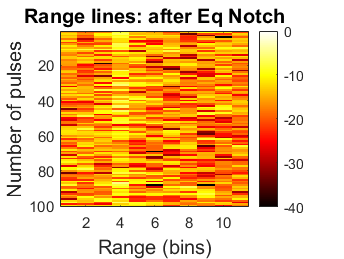

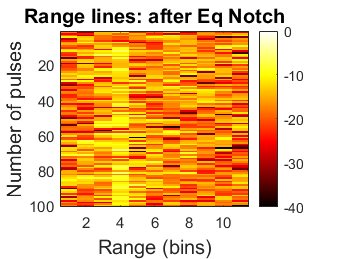

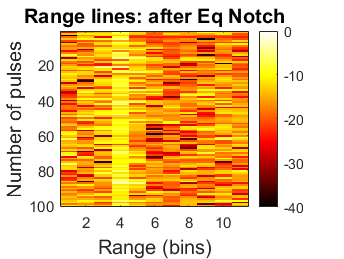

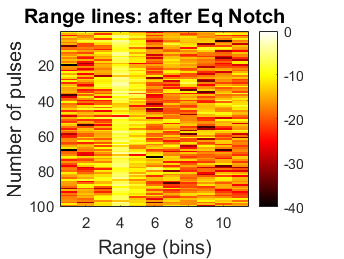


%loop to calculate detections per screenshotted section
for z = 1:numIterations
    if z <numIterations
    RangeProfiles = RangeProfiles_AfterEqNotch(1+stepSize*(z-1):stepSize*z,13:23);
    [NumOfPulses,NumOfRangeBins]=size(RangeProfiles);
    fontsize1 = 12;
    clims = [-40 0];
    
    % Plot range lines
    figure; axes('fontsize',fontsize1);
    imagesc(20*log10(abs(RangeProfiles)./MaxRangeLine),clims);
    colormap('hot');
    colorbar;
    xlabel('Range (bins)','fontsize',fontsize1);
    ylabel('Number of pulses','fontsize',fontsize1);
    title('Range lines: after Eq Notch','fontsize',fontsize1);
    
    % Get the current figure handl
    fig = gcf;
    frame = getframe(fig);
    % Convert the captured frame to an RGB image:
    rgb_image = frame.cdata;
    % Convert RGB image to HSV color space:
    hsv_image = rgb2hsv(rgb_image);
    %trimm so colourbar is removed from image
    hsv_image = hsv_image(41:466, 83:566, :);
    
    
    % Define hue and saturation thresholds for yellow:
    hue_threshold = [0, 0.9]; % Adjust as needed
    saturation_threshold = [0, 0.8]; % Adjust as needed

    % Create target locations based on hue and saturation thresholds:
    target_pnts = (hsv_image(:,:,1) >= hue_threshold(1) & hsv_image(:,:,1) <= hue_threshold(2)) & ...
              (hsv_image(:,:,2) >= saturation_threshold(1) & hsv_image(:,:,2) <= saturation_threshold(2));

    %Resize matices to same size as dataset
    target_pnts = double(target_pnts);
    [numtargetRows,numtargetCols] = size(target_pnts);
    
    target_pnts_resized = zeros(numtargetRows, NumOfRangeBins);
    %resize rows
    for i = 1:numtargetRows
    targetsOriginalRowsize = 1:numel(target_pnts(i,:));
    targetsNewRowSize = linspace(1, numtargetCols, NumOfRangeBins);
    target_pnts_resized(i, :) = interp1(targetsOriginalRowsize, target_pnts(i,:), targetsNewRowSize, 'linear');
    end
    target_pnts_resized = abs(target_pnts_resized) ==1;
    target_pnts_resized = double(target_pnts_resized);
    finalTargetPnts = zeros(NumOfPulses, NumOfRangeBins); 
    
    %resize coloumns
    for i = 1:NumOfRangeBins
    targetsOriginalColsize = 1:numel(target_pnts_resized(:,i));
    targetsNewRowSize = linspace(1, numtargetRows, NumOfPulses);
    finalTargetPnts(:, i) = interp1(targetsOriginalColsize, target_pnts_resized(:,i), targetsNewRowSize, 'linear');
    end
    
    finalTargetPnts = abs(finalTargetPnts) ==1;
    finalTargetPnts = double(finalTargetPnts);
    Target_locations_DS1(1+stepSize*(z-1):stepSize*z,13:23) = finalTargetPnts;

%this is for the last screenshotted image that amy have a different size
%than expected - FOLLOWS SAME PROCESS AS ABOVE
elseif z == numIterations
       RangeProfiles = RangeProfiles_AfterEqNotch(1+stepSize*(z-1):end,13:23);
    [NumOfPulses,NumOfRangeBins]=size(RangeProfiles);
    fontsize1 = 12;
    clims = [-40 0];
    
    % Plot range lines
    figure; axes('fontsize',fontsize1);
    imagesc(20*log10(abs(RangeProfiles)./MaxRangeLine),clims);
    colormap('hot');
    colorbar;
    xlabel('Range (bins)','fontsize',fontsize1);
    ylabel('Number of pulses','fontsize',fontsize1);
    title('Range lines: after Eq Notch','fontsize',fontsize1);
    
    % Get the current figure handl
    fig = gcf;
    frame = getframe(fig);
    % Convert the captured frame to an RGB image:
    rgb_image = frame.cdata;
    % Convert RGB image to HSV color space:
    hsv_image = rgb2hsv(rgb_image);
    hsv_image = hsv_image(41:466, 83:566, :);
    
    hue_threshold = [0, 0.9]; % Adjust as needed
    saturation_threshold = [0, 0.8]; % Adjust as needed
    % Create binary mask based on hue and saturation thresholds:
    target_pnts = (hsv_image(:,:,1) >= hue_threshold(1) & hsv_image(:,:,1) <= hue_threshold(2)) & ...
              (hsv_image(:,:,2) >= saturation_threshold(1) & hsv_image(:,:,2) <= saturation_threshold(2));
    
    target_pnts = double(target_pnts);
    [numtargetRows,numtargetCols] = size(target_pnts);
    
    target_pnts_resized = zeros(numtargetRows, NumOfRangeBins);
    for i = 1:numtargetRows
    targetsOriginalRowsize = 1:numel(target_pnts(i,:));
    targetsNewRowSize = linspace(1, numtargetCols, NumOfRangeBins);
    target_pnts_resized(i, :) = interp1(targetsOriginalRowsize, target_pnts(i,:), targetsNewRowSize, 'linear');
    end
    
    target_pnts_resized = abs(target_pnts_resized) ==1;
    target_pnts_resized = double(target_pnts_resized);
    finalTargetPnts = zeros(NumOfPulses, NumOfRangeBins); 
    
    for i = 1:NumOfRangeBins
    targetsOriginalColsize = 1:numel(target_pnts_resized(:,i));
    targetsNewRowSize = linspace(1, numtargetRows, NumOfPulses);
    finalTargetPnts(:, i) = interp1(targetsOriginalColsize, target_pnts_resized(:,i), targetsNewRowSize, 'linear');
    end
    
    finalTargetPnts = abs(finalTargetPnts) ==1;
    Target_locations_DS1(1+stepSize*(z-1):end,13:23) = finalTargetPnts; 
    end
end

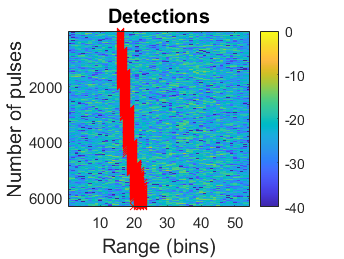







% Manual removal of noise data points registered as targets 
Target_locations_DS1(4537:end, 18) = 0;
Target_locations_DS1(5195:end, 19) = 0;
Target_locations_DS1(1:4936, 22) = 0;
Target_locations_DS1(1:5309, 23) = 0;
Target_locations_DS1(:, 1:15) = 0;
Target_locations_DS1(2014:end, 16) = 0;
Target_locations_DS1(3110:end, 17) = 0;
Target_locations_DS1(1:4000, 23) = 0;
Target_locations_DS1(1:4700, 22) = 0;
Target_locations_DS1(1:4740, 21) = 0;
Target_locations_DS1(1:4000, 20) = 0;
Target_locations_DS1(1:2785, 19) = 0;
Target_locations_DS1(1:1400, 18) = 0;
Target_locations_DS1(1:680, 17) = 0;


% % Save the dataset to a .mat file
save('Target_locations_DS1.mat', 'Target_locations_DS1');

%plotting final detection locations
fontsize1 = 12;
[MaxRangeLine MaxIdx] = max(max(abs(RangeProfiles_AfterEqNotch)));
clims = [-40 0];
figure; axes('fontsize',fontsize1);
imagesc(20*log10(abs(RangeProfiles_AfterEqNotch)./MaxRangeLine),clims);
colorbar;
xlabel('Range (bins)','fontsize',fontsize1);
ylabel('Number of pulses','fontsize',fontsize1);
title('Detections','fontsize',fontsize1);
hold on

[pulseCoord, rangeCoord] = find(Target_locations_DS1 == 1);

% Plot 'x' at positions where matrix value is 1
scatter(rangeCoord, pulseCoord, 'rx');